# Data Analysis

## Piano inclinato

clear

% importing data
df1=readtable("experimental-data-1.csv")

df1 = 9×4 table
    grandezza    valore    incertezza     udm 
    _________    ______    __________    _____

     {'h2'}      0.412       0.001       {'m'}
     {'h1'}      1.122       0.001       {'m'}
     {'s1'}      1.992       0.001       {'m'}
     {'s2'}      0.713       0.001       {'m'}
     {'m1'}      15.19        0.01       {'g'}
     {'m2'}      98.82        0.01       {'g'}
     {'m3'}      130.6        0.01       {'g'}
     {'m4'}      13.79        0.01       {'g'}
     {'m5'}       26.6        0.01       {'g'}


df2=readtable("experimental-data-2.csv")

df2 = 200×5 table
    index    massa      t      inertezza     udm 
    _____    ______    ____    _________    _____

      1      {'m1'}    1.65      0.01       {'s'}
      2      {'m1'}     1.6      0.01       {'s'}
      3      {'m1'}    1.66      0.01       {'s'}
      4      {'m1'}    2.18      0.01       {'s'}
      5      {'m1'}    1.54      0.01       {'s'}
      6      {'m1'}    1.74      0.01       {'s'}
      7      {'m1'}    1.47      0.01       {'s'}
      8      {'m1'}    1.55      0.01       {'s'}
      9      {'m1'}     1.8      0.01       {'s'}
     10      {'m1'}    1.75      0.01       {'s'}
     11      {'m1'}    1.94      0.01       {'s'}
     12      {'m1'}    2.05      0.01       {'s'}
     13      {'m1'}    2.67      0.01       {'s'}
     14      {'m1'}    1.56      0.01       {'s'}
     15    

tools=readtable("tools.csv");

% tempi
t=df2.t;
tm1=t(1:40,:);
%histfit(t1m1)
%hist(tm1)


tm2=df2.t(41:80,:);
%hist(tm2)

tm3=df2.t(81:120,:);
%hist(tm3)

tm4=df2.t(121:160,:);
%hist(tm4)

tm5=df2.t(161:200,:);
%hist(tm5)

% spazio
s1=df1.valore(3);
s2=df1.valore(4);
s=s1-s2

s = 1.2790


% altezza
h2=df1.valore(1);
h1=df1.valore(2);
h=h1-h2

h = 0.7100


% angolo
rteta=asin(h./s)

rteta = 0.5885

dteta=(180./pi)*rteta

dteta = 33.7191

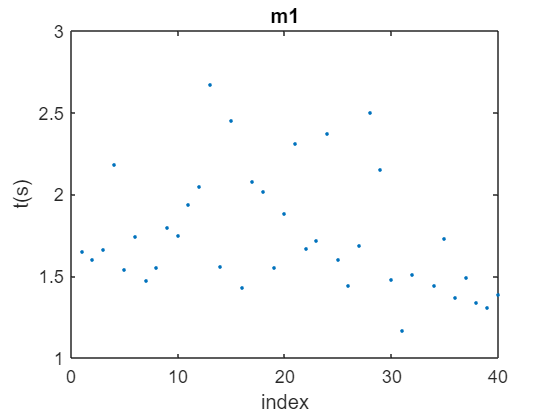


figure
plot(1:40,tm1,".")
title('m1')
ylabel('t(s)')
xlabel('index')

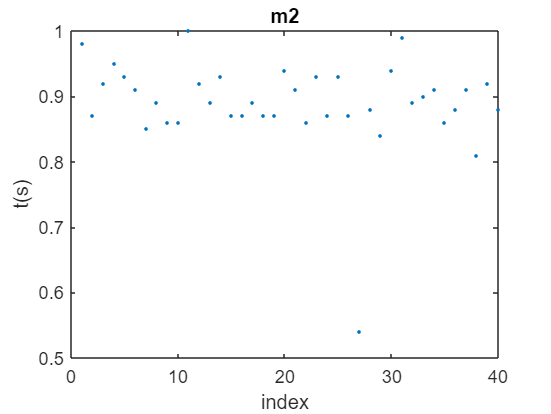


figure
plot(1:40,tm2,".")
title('m2')
ylabel('t(s)')
xlabel('index')

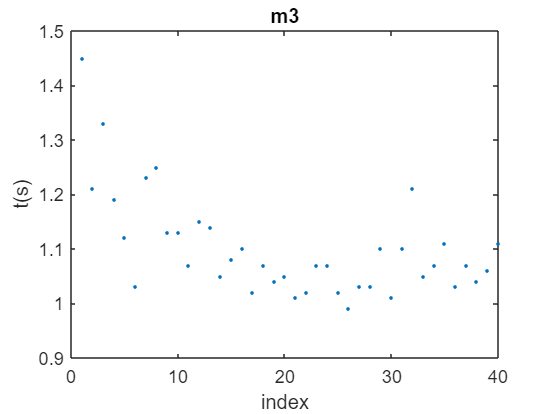


figure
plot(1:40,tm3,".")
title('m3')
ylabel('t(s)')
xlabel('index')

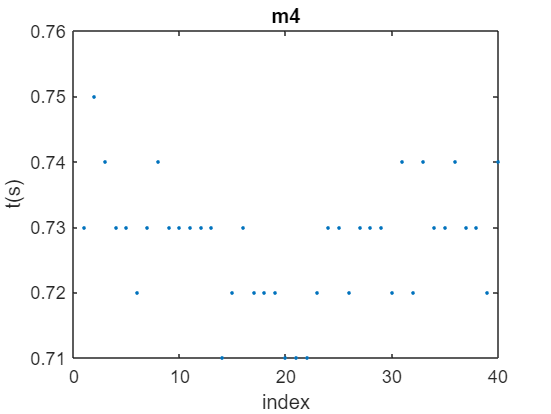


figure
plot(1:40,tm4,".")
title('m4')
ylabel('t(s)')
xlabel('index')

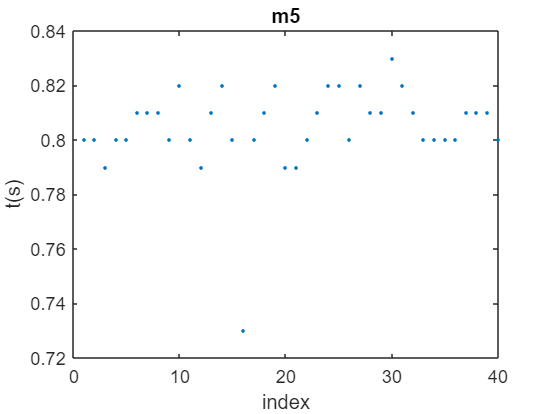


figure
plot(1:40,tm5,".")
title('m5')
ylabel('t(s)')
xlabel('index')


% subplot
% subplot(5,1,1)
% plot(1:40,tm1,".")
% title('m1')
% ylabel('t(s)')
% xlabel('index')
% subplot(5,1,2)
% plot(1:40,tm2,".")
% title('m2')
% ylabel('t(s)')
% xlabel('index')
% subplot(5,1,3)
% plot(1:40,tm3,".")
% title('m3')
% ylabel('t(s)')
% xlabel('index')
% subplot(5,1,4)
% plot(1:40,tm4,".")
% title('m4')
% ylabel('t(s)')
% xlabel('index')
% subplot(5,1,5)
% plot(1:40,tm5,".")
% title('m5')
% ylabel('t(s)')
% xlabel('index')

% test g
g=(2.*s)/(sin(rteta).*(mean(tm1)).^2)

g = NaN